filepath = "C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv" 

filepath = "C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv"

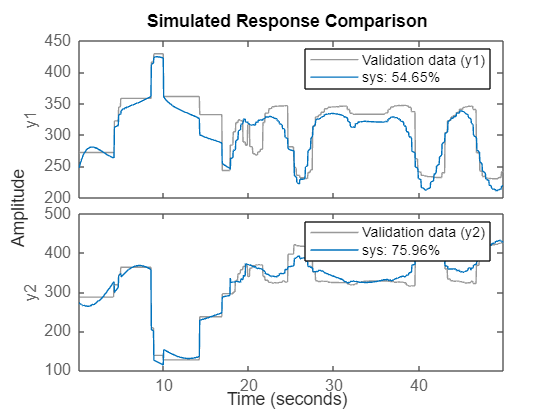

data = readtable(filepath);

% Extract data (modify column indices if necessary)
time = data{:, 1};  % time
x1 = data{:, 2};    % current x
y1 = data{:, 3};    % tilt angle x
x2 = data{:, 4};    % another variable
y2 = data{:, 5};    % another variable
tiltx = data{:, 6};  
tilty = data{:, 7};  
U = [x1, y1];  % input data
Y = [x2, y2];  % output data

% Generate time (or sample index) for the system (assume unit time step)
numSamples = length(y1);  
Ts = data{2,1} - data{1,1};  % sampling time from the data

% Create input-output data for system identification
inputData = U;  % Setpoint is the input
outputData = Y;  % System output is the observed x1

data_id = iddata(outputData, inputData, Ts);  % Create an iddata object
% Initialize variables for storing comparison results

    sys = tfest(data_id, 2,2); % (2,2) for x (2,2) for y best performance tfest
  %  [ss_model,~,~] = tf2ss(tf_model.num{1}, tf_model.den{1});
    
    % Use the compare function to calculate fit between the model and the data
    compare(data_id, sys);